## Interpretacion geometrica de SVD

A = [2 2; 3 5]

A =      2     2
     3     5


[U,S,V] = svd(A)

U =    -0.4298   -0.9029
   -0.9029    0.4298


S =     6.4510         0
         0    0.6201


V =    -0.5531   -0.8331
   -0.8331    0.5531


 Determinante de U

det(U)

ans = -1

Determinante de V

det(V)

ans = -1.0000

Grafico de circunferencia unitaria

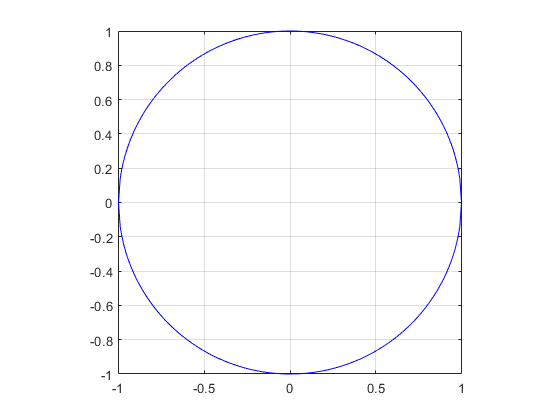

x = -1:0.01:1;
y = sqrt(1-x.^2);
plot(x,y,'b', x,-y, 'b')
grid on
daspect([1 1 1])
axis square

F = U * [x; y]

F =     0.4298    0.2981    0.2415    0.1974    0.1598    0.1263    0.0959    0.0678    0.0415    0.0167   -0.0068   -0.0292   -0.0507   -0.0713   -0.0912   -0.1103   -0.1289   -0.1469   -0.1644   -0.1814   -0.1979   -0.2141   -0.2298   -0.2452   -0.2602   -0.2749   -0.2893   -0.3034   -0.3172   -0.3307   -0.3440   -0.3570   -0.3698   -0.3824   -0.3947   -0.4068   -0.4187   -0.4305   -0.4420   -0.4533   -0.4645   -0.4755   -0.4863   -0.4969   -0.5074   -0.5177   -0.5279   -0.5379   -0.5478   -0.5575
    0.9029    0.9545    0.9704    0.9803    0.9872    0.9920    0.9954    0.9977    0.9991    0.9999    1.0000    0.9996    0.9987    0.9975    0.9958    0.9939    0.9917    0.9891    0.9864    0.9834    0.9802    0.9768    0.9732    0.9695    0.9656    0.9615    0.9572    0.9529    0.9484    0.9437    0.9390    0.9341    0.9291    0.9240    0.9188    0.9135    0.9081    0.9026    0.8970    0.8913    0.8856    0.8797    0.8738    0.8678    0.8617    0.8555    0.8493    0.8430    0.8366    0

F2 = U * [x; -y]

F2 =     0.4298    0.5528    0.6009    0.6364    0.6654    0.6902    0.7120    0.7316    0.7493    0.7655    0.7804    0.7942    0.8071    0.8191    0.8304    0.8410    0.8509    0.8603    0.8692    0.8776    0.8856    0.8931    0.9003    0.9070    0.9135    0.9196    0.9254    0.9308    0.9361    0.9410    0.9457    0.9501    0.9543    0.9583    0.9620    0.9655    0.9688    0.9720    0.9749    0.9776    0.9802    0.9826    0.9848    0.9869    0.9887    0.9905    0.9920    0.9935    0.9947    0.9959
    0.9029    0.8333    0.7994    0.7714    0.7465    0.7236    0.7021    0.6818    0.6623    0.6435    0.6253    0.6077    0.5905    0.5737    0.5572    0.5411    0.5253    0.5097    0.4944    0.4793    0.4645    0.4498    0.4353    0.4210    0.4069    0.3929    0.3791    0.3654    0.3519    0.3384    0.3251    0.3120    0.2989    0.2859    0.2731    0.2603    0.2477    0.2351    0.2226    0.2102    0.1979    0.1857    0.1736    0.1616    0.1496    0.1377    0.1259    0.1141    0.1024    

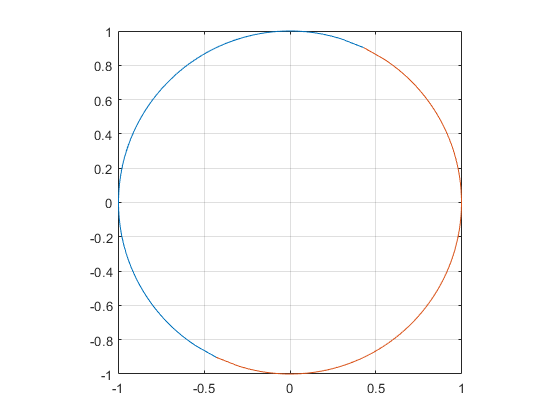

plot(F(1,:), F(2,:), F2(1,:), F2(2,:))
grid on
daspect([1 1 1])
axis square

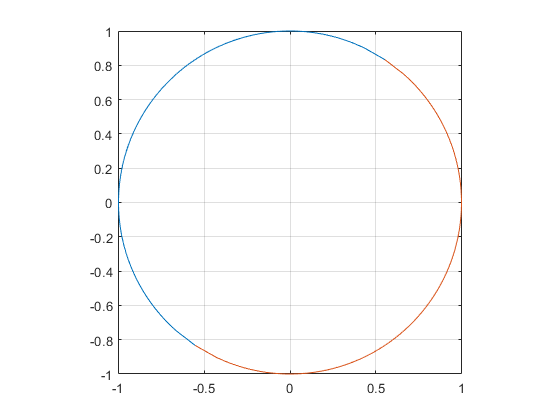

R = V * [x; y];
R2 = V * [x; -y];
plot(R(1,:), R(2,:), R2(1,:), R2(2,:))
grid on
daspect([1 1 1])
axis square

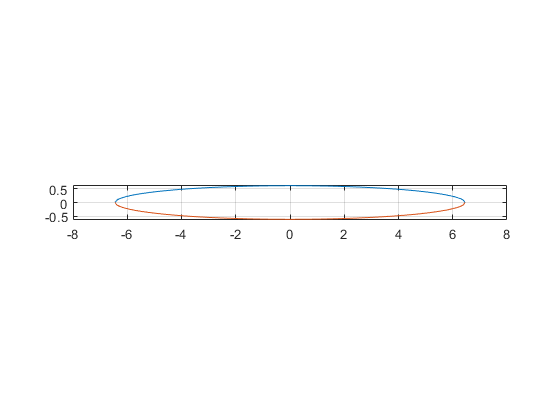

R = S * [x; y];
R2 = S * [x; -y];
plot(R(1,:), R(2,:), R2(1,:), R2(2,:))
grid on
daspect([1 1 1])